% P9.2

% (a)
clear all
syms s K
% Ls의 pole을 구하는 과정.
Ls = K/(s*(s^2+2*s+5));
[num, den] = numden(Ls);
eqn = den == 0;
s = solve(eqn,s)    % s = 0, -1±2i (Ls의 양수부 pole은 0개이다.)

$$s = \left(\begin{array}{c} 0\\ -1-2\,\mathrm{i}\\ -1+2\,\mathrm{i} \end{array}\right)$$

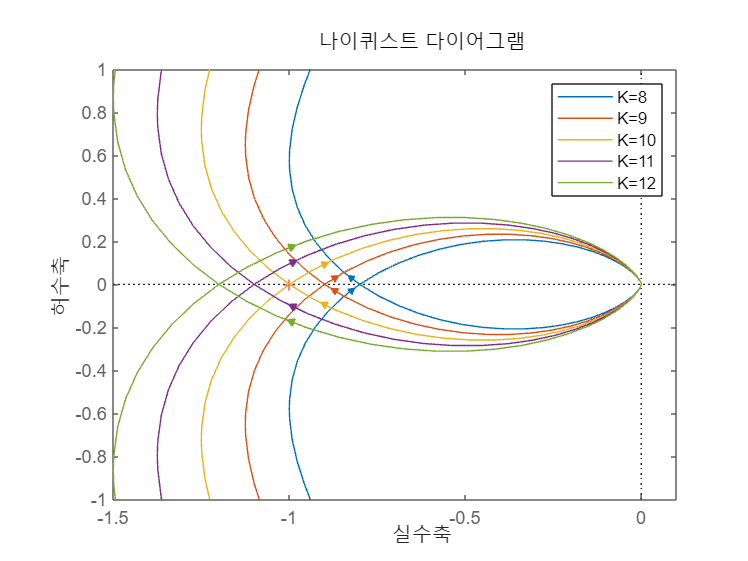


s = tf('s');
sys_leg1 = [];
for K = 8:12
    Ls = K/(s*(s^2+2*s+5));
    nyquist(Ls);
    K1 = string(K);
    sys_leg = strcat('K=',K1);
    sys_leg1 = cat(1,sys_leg1,sys_leg);
    hold on
end
axis([-1.5 0.1 -1 1])
legend(sys_leg1);
hold off

% K=10 일 때는 nyquist 선도가 (-1,0)을 지나며,
% K>10 일 때는 nyquist 선도가 (-1,0)을 시계 방향으로 1번 이상 둘러싸고,
% K<10 일 때는 nyquist 선도가 (-1,0)을 0번 둘러싼다.
% 
% Ls의 양수부 pole이 0개이므로, 시스템이 안정적이기 위해서는 
% nyquist 선도가 (-1,0)을 둘러싸면 안 된다.
% 따라서 K<10 일 때 시스템은 안정하다.

% (b)
clear all
syms s K
% Ls의 pole을 구하는 과정.
Ls = K*(s+2)/(s^2*(s+5));
[num, den] = numden(Ls);
eqn = den == 0;
s = solve(eqn,s)    % s = 0, -5 (Ls의 양수부 pole은 0개이다.)

$$s = \left(\begin{array}{c} -5\\ 0\\ 0 \end{array}\right)$$

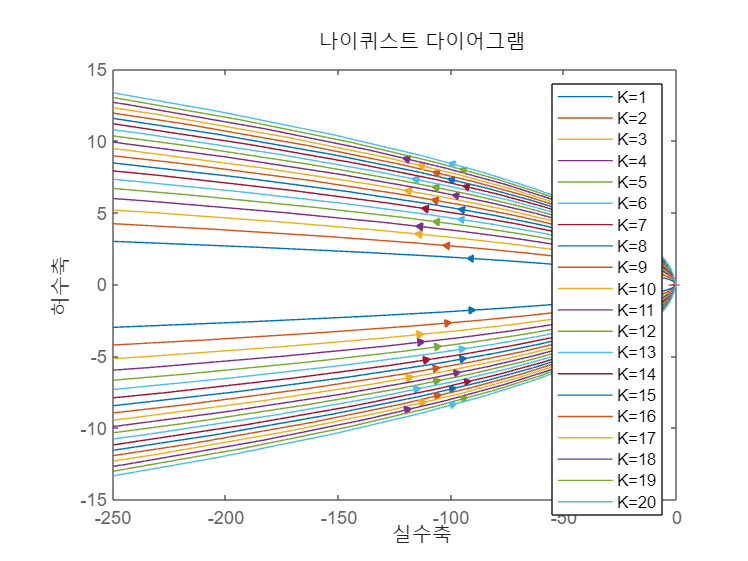


s = tf('s');
sys_leg1 = [];
for K = 1:20
    Ls = K*(s+2)/(s^2*(s+5));
    nyquist(Ls);
    K1 = string(K);
    sys_leg = strcat('K=',K1);
    sys_leg1 = cat(1,sys_leg1,sys_leg);
    hold on
end

legend(sys_leg1);
hold off

% 선도가 실수축 음의 방향으로 발산하긴 하지만,
% Ls의 양수부 pole이 0개 일 때 *시계방향*으로 감싸게 된다는 전제조건이 있다.
% 만약 nyquist 선도가 (-1,0)을 감싸게 된다 하더라도 시계방향이 아니기 때문에
% K 값에 관계없이 nyquist 선도는 (-1,0)을 감싸거나 지나치지 않는다.
% 따라서 K값에 관계없이 시스템은 안정하다.